# SISO control design:

In this task we're going to design 3 SISO controllers for our 6-DOF vehicle model.  The controllers are:

- Altitude (ie: Z) control

- YAW angle control

- PITCH angle control  (NB: the ROLL controller will be identical)

The design requirements for this task are:

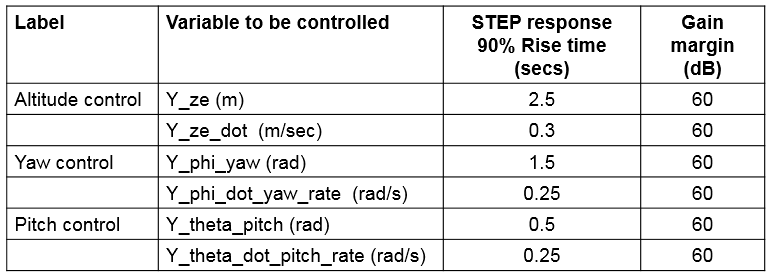

`Bradley Horton : 01-Jun-2016, bradley.horton@mathworks.com.au`

## Prerequisite:

Before commencing this task you need to run the `bh_task_find_trim_and_linearise.mlx` script to create required variables (eg: transfer function objects)  that are used in this control design task.

assert(1==exist('sys_6dof_lin'), 'you have NOT run the ***bh_task_find_trim_and_linearise***');

## Our SISO controller structure:

For each of these SISO controllers the structure that we'll use will involve 2 proportional controllers configured in a cascade loop.  The inner loop is the velocity loop and the outer loop is the position loop. This control structure is shown below:

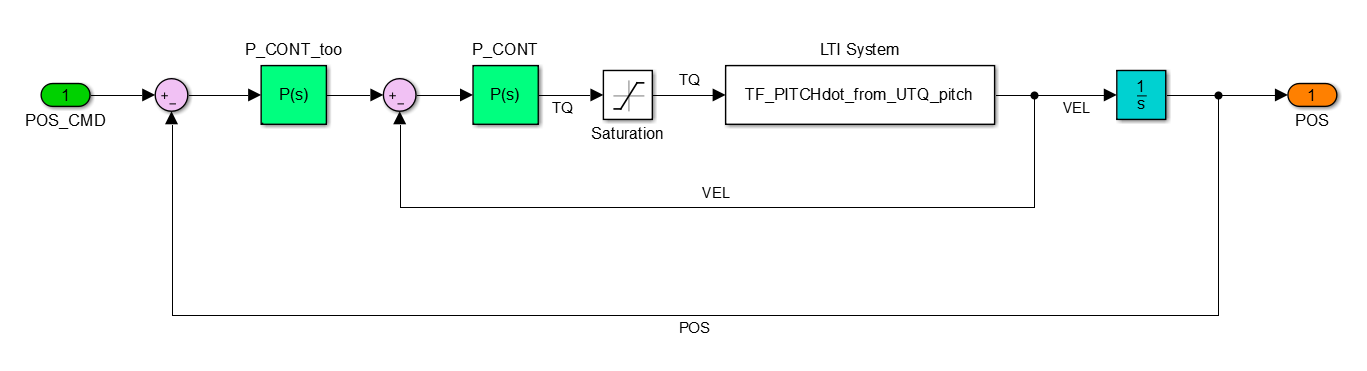

Note we can also represent this structure as:

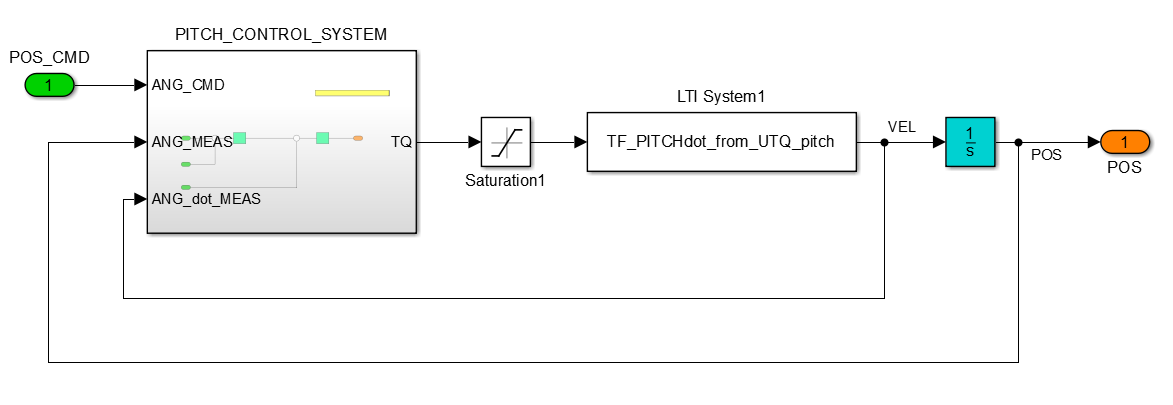

To design each controller we'll design the INNER velocity loop controller first, and then we'll design the OUTER positional controller.  The linear plants for each of these 3 control design tasks are:

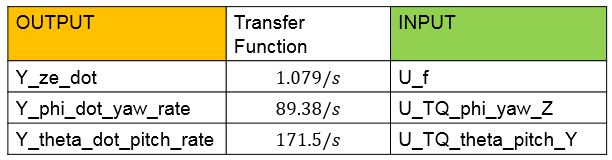

Create the 3 linear plant transfer functions:

TF_ZEdot_from_Uf           = tf(sys_6dof_lin('Y_ze_dot', 'U_f'));
TF_YAWdot_from_UTQ_yaw     = tf(sys_6dof_lin('Y_phi_dot_yaw_rate', 'U_TQ_phi_yaw_Z'));
TF_PITCHdot_from_UTQ_pitch = tf(sys_6dof_lin('Y_theta_dot_pitch_rate', 'U_TQ_theta_pitch_Y'));

Echo these:

[TF_ZEdot_from_Uf,  TF_YAWdot_from_UTQ_yaw, TF_PITCHdot_from_UTQ_pitch ]

## Now do the design:

Open the Simulink model `bh_do_CONTROL_DESIGN_via_PID_TUNER.slx` and consider the subsystem called "INITIAL_PITCH_CONTROL_SYSTEM". Launch the PID tuner app for each of the green P blocks and design according to the requirements. NOTE: although all of our designs are just "P-controllers", the tuner app is called the "PID tuner" - hey, no big deal !

open_system('bh_do_CONTROL_DESIGN_via_PID_TUNER.slx')

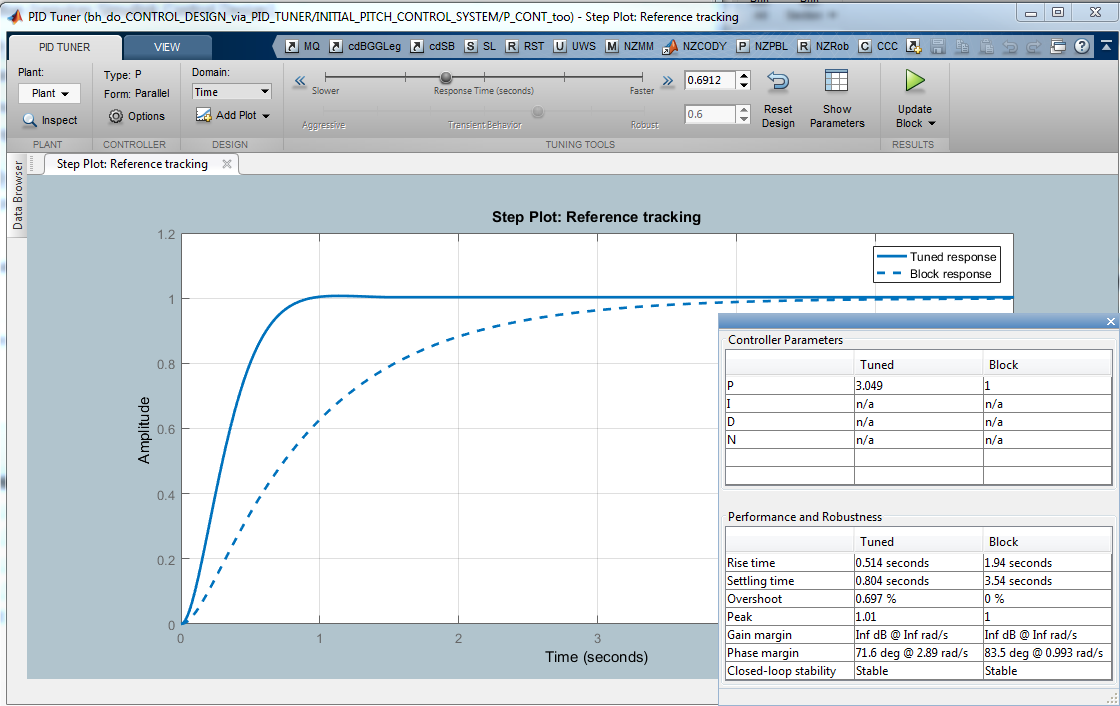

And you can repeat this design for the YAW and ALTITUDE controllers.  The final designs that I have made are also shown in the `bh_do_CONTROL_DESIGN_via_PID_TUNER.slx` model, and they are:

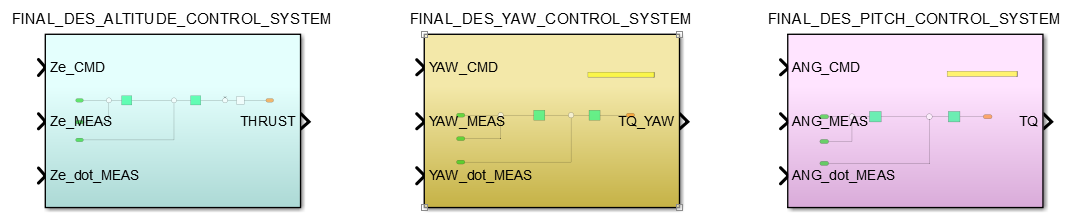

# But what about the NON-linear 6-DOF model ?

The controllers that we've just designed used a linear approximation of our 6-DOF model. SO we now need to try the controllers with our NON-linear model.  Open the model  `bh_test_LINCONT_on_NONLIN_plant.slx` and see how the controllers performed - here we apply STEPS and pulses of:

- Ze = 1 (m)

- Pitch = 30 (degrees)

- YAW = 60 (degrees)

-